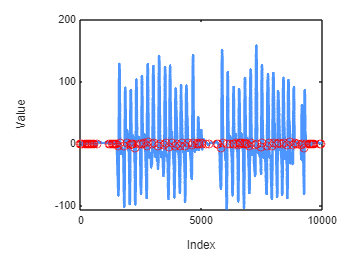

time=out.Time.Data;
acc_thigh=out.estimated_acc_thigh.Data(1:3,:,:);
acc_shank=out.estimated_acc.Data(1:3,:,:);
gyro_thigh=out.estimated_gyro_thigh.Data(1:3,:,:);
gyro_shank=out.estimated_gyro.Data(1:3,:,:);


[acc_thigh_x, acc_thigh_y, acc_thigh_z] = deal(squeeze(acc_thigh(1, :, :)), squeeze(acc_thigh(2, :, :)), squeeze(acc_thigh(3, :, :)));
[acc_shank_x, acc_shank_y, acc_shank_z] = deal(squeeze(acc_shank(1, :, :)), squeeze(acc_shank(2, :, :)), squeeze(acc_shank(3, :, :)));
[gyro_thigh_x, gyro_thigh_y, gyro_thigh_z] = deal(squeeze(gyro_thigh(1, :, :)), squeeze(gyro_thigh(2, :, :)), squeeze(gyro_thigh(3, :, :)));
[gyro_shank_x, gyro_shank_y, gyro_shank_z] = deal(squeeze(gyro_shank(1, :, :)), squeeze(gyro_shank(2, :, :)), squeeze(gyro_shank(3, :, :)));

%4 -1) 보행 환경에 따른 데이터 분류 위해 zero-crossing 찾기
time=interp1(1:length(time),time, linspace(1,length(time),10000),'linear');
gyro_thigh_z_interp=interp1(1:length(gyro_shank_z),gyro_shank_z, linspace(1,length(gyro_shank_z),10000),'linear');
point=find(diff(sign(gyro_thigh_z_interp))~=0);

figure;
plot(gyro_thigh_z_interp, 'Color', [77/255, 150/255, 255/255], 'LineWidth', 2);
hold on;
plot(point, gyro_thigh_z_interp(point), 'ro');
xlabel('Index');
ylabel('Value');

string(time(8800))

ans = "1027.7139"